% clear all;
clc; close all;

% load('DI_eigenvectors.mat')
% load('Eigvec_Active_normal.mat')

## Plot Eigenvalues

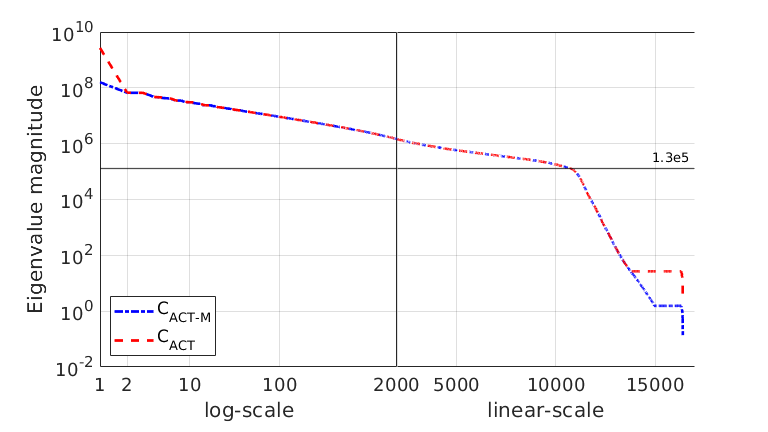

x = (1:1:16384);
% yuc = sqrt(1e-4*S_uc);
% ycc = sqrt(1e-4*S_cc);

yuc = sqrt(S_uc);
ycc = sqrt(S_cc);

figure('Units','normalized','Position',[0 0 0.15 0.3]);


t = tiledlayout(1,2,'TileSpacing','none');
% bgAx = axes(t,'XTick',[],'YTick',[],'Box','on');
% bgAx.Layout.TileSpan = [1 2];


ax1 = axes(t);
ax1.Layout.Tile = 1;

loglog(x,yuc, 'b-.','LineWidth',2,'DisplayName','C_{ACT-M}'); hold on
loglog(x,ycc, 'r--','LineWidth',2,'DisplayName','C_{ACT}');

% yline(ax1,1e2,'k-', 'LineWidth',1, 'HandleVisibility','off');
yline(ax1,1.3e5,'k-', 'LineWidth',1, 'HandleVisibility','off');
% yline(ax1,1e8,'k-', 'LineWidth',1, 'HandleVisibility','off');

% xline(ax1,2000,':');
% ax1.Box = 'on';
xlim(ax1,[0 2000])
xlabel(ax1, 'log-scale')
xticks([1 2 10 100])
yticks([1e-2 1e0 1e2 1e4 1e6 1e8 1e10 ])
ax1.TickLength = [0 0];
grid on
ylabel('Eigenvalue magnitude')
legend('Location',"southwest")
set(gca, 'YMinorTick','off ', 'YMinorGrid','off ', 'XMinorTick','off ', 'XMinorGrid','off ')
set(gca,'FontSize', 14, 'fontname', 'Times New Roman')

% Create second plot
ax2 = axes(t);
ax2.Layout.Tile = 2;
semilogy(x,yuc, 'b-.','LineWidth',2,'DisplayName','C_{ACT-M}'); hold on
semilogy(x,ycc, 'r--','LineWidth',2,'DisplayName','C_{ACT}');

% yline(ax2,1e2,'k-','1e2', 'LineWidth',1, 'HandleVisibility','off');
yline(ax2,1.3e5,'k-','1.3e5', 'LineWidth',1, 'HandleVisibility','off');
% yline(ax2,1e8,'k-','1e8', 'LineWidth',1, 'HandleVisibility','off');

ax2.YAxis.Visible = 'off';
ax2.TickLength = [0 0];
ax.YAxis.Color = 'w';

xlim(ax2,[2000 17000])
xlabel(ax2,'linear-scale')
grid on
% box on
% legend('Location',"northeast")
xticks([2000 5000 10000 15000])
yticks([1e-2 1e0 1e2 1e4 1e6 1e8 1e10 ])
ax2.Box = 'on';
set(gca, 'YMinorTick','off ', 'YMinorGrid','off ', 'XMinorTick','off ', 'XMinorGrid','off ')
set(gca,'FontSize', 14, 'fontname', 'Times New Roman')


% Link the axes
linkaxes([ax1 ax2], 'y')

saveas(gcf,['X_ray_Eigenvalue_comparison'],'epsc')

function [A]=Data(N)

target = phantom('Modified Shepp-Logan',N);

% Choose measurement angles (given in degrees, not radians).

Nang    = N;
angle0  = -90;
measang = angle0 + [0:(Nang-1)]/Nang*180;

% Initialize measurement matrix of size (M*P) x N^2, where M is the number of
% X-ray directions and P is the number of pixels that Matlab's Radon
% function gives.
P  = length(radon(target,0));
M  = length(measang);
A = zeros(M*P,N^2);

% Construct measurement matrix column by column. The trick is to construct
% targets with elements all 0 except for one element that equals 1.
for mmm = 1:M
    for iii = 1:N^2
        tmpvec                  = zeros(N^2,1);
        tmpvec(iii)             = 1;
        A((mmm-1)*P+(1:P),iii) = radon(reshape(tmpvec,N,N),measang(mmm));
    end
end
end